# Projeto do dia 02/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;
% Abrindo dados anteriores para recuperar os ganhos calculados
load("ResultadosFinais.mat")

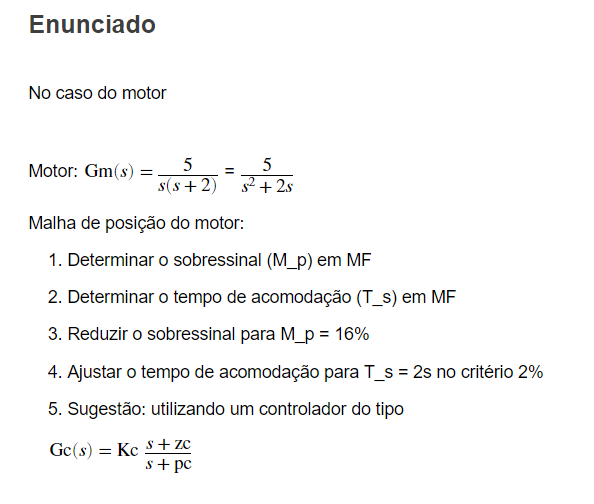


$$Gm(s) = \frac{5}{s^2+2s}=\frac{5}{s(s+2)}$$



Gm = tf(5,[1 2 0]) 

Gm =
 
      5
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



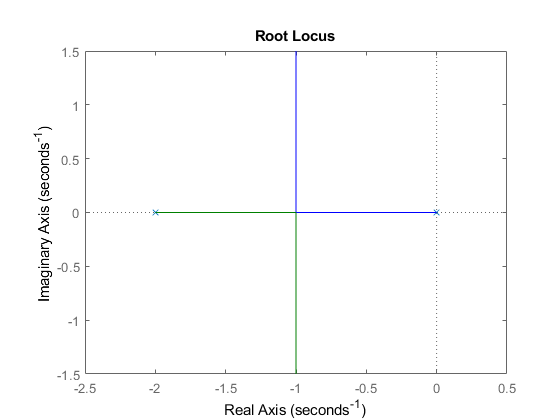

rlocus(Gm)

Gmf=feedback(Gm,1)

Gmf =
 
        5
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.




% Usando o stepinfo - struct com os dados de resposta ao degrau como
% entrada
info = stepinfo(Gmf);
Mp = info.Overshoot % Resposta da 1

Mp = 20.7866

Ts = info.SettlingTime % Resposta da 2

Ts = 3.7352


$$Gc(s) = Kp\frac{s+zc}{s+pc}$$


%Usando o sisotool - respostas da 1 e 2


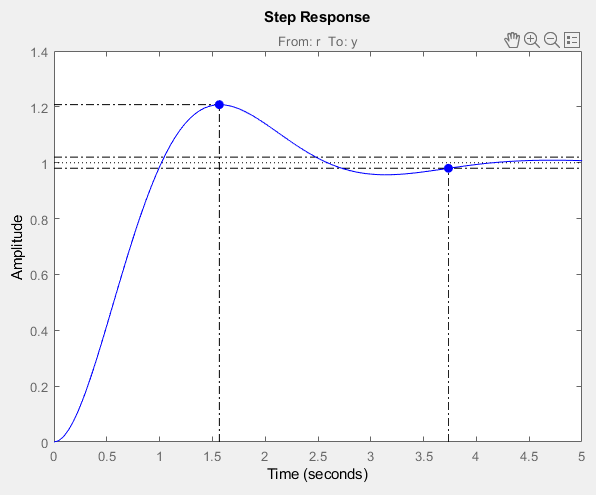

% Reduzir o sobressinal para 16%
% Via sisotool
% Resposta da 3
Kp = C;
Gmf = feedback(Kp*Gm,1)

Gmf =
 
        3.9159
  ------------------
  (s^2 + 2s + 3.916)
 
Continuous-time zero/pole/gain model.



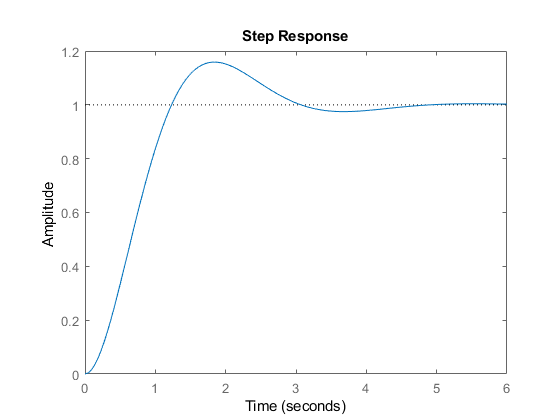

step(Gmf)


% Via sisotool, percebe-se que não há ganho que satisfaça as afirmações 3 e
% 4 ao mesmo tempo sem usar o ganho sugerido

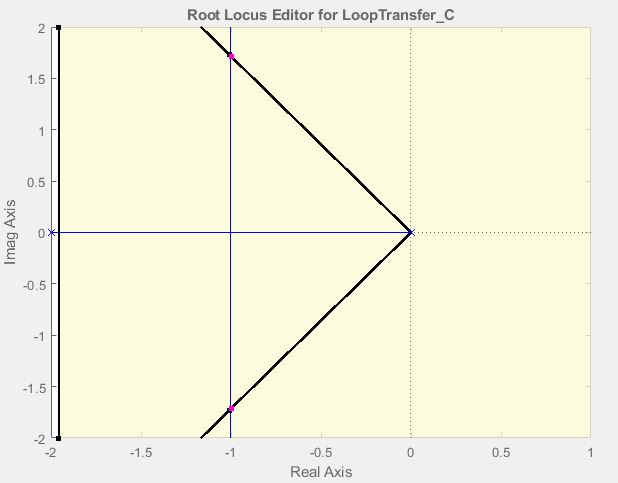

% Novo C calculado pelas fotos do sisotool que vêm a seguir
Kp_novo = NovoC

Kp_novo =
 
  3.3085 (s+1.986)
  ----------------
     (s+4.049)
 
Name: NovoC
Continuous-time zero/pole/gain model.



Gmf = feedback(Kp_novo*Gm,1)

Gmf =
 
          16.543 (s+1.986)
  --------------------------------
  (s+1.982) (s^2 + 4.067s + 16.58)
 
Continuous-time zero/pole/gain model.



% step(Gmf)
info = stepinfo(Gmf);
Mp_novo = info.Overshoot

Mp_novo = 16.2391

Ts_novo = info.SettlingTime

Ts_novo = 1.9850

% Via sisotool

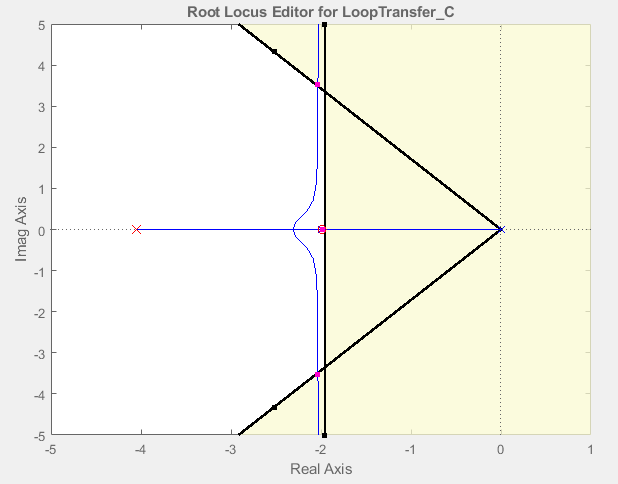

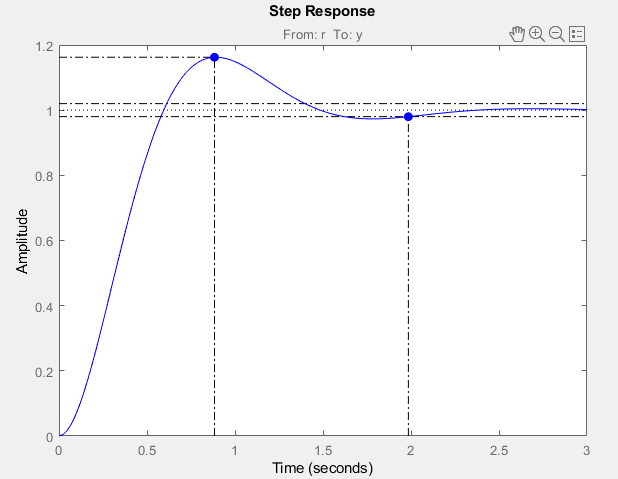

% salvando os dados
save("ResultadosFinais.mat")